# BME 3053C Final Project Part 2

Authors: Miraj Patel

Group Members: Jessica Shubin and Rachel Garner

Course: BME 3053C Computer Applications for BME

Term: Spring2021

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

Email: mirajpatel@ufl.edu

April 13, 2021

### **** Note that this code requires the use of the 647 by 6 excel table that is provided in the Github link NOT the one created by the sample data because that one has only 100 images. The name of this file is 'Summary.xls'. 

### The table includes all the images (437 benign, 210 malignant) that were processed from the original data set and not just the ones in the sample****

clc;clear;clear all;

image_table = xlsread('Summary.xls');  % loads the table from the image processing steps

%Decision Tree and LDA Validation Testing

train = 500;             %number of images in training set
errorsTREE = [];         % validation error rate for the decision tree
errorsLDA = [];          % validation error rate for the LDA algorithm
final_testLDA = [];      % test error rate for the model with the lower validation error rate (LDA)
final_testDT = [];       % test the error rate for the Decision tree

for j = 1:100                                 % 100 repetitions 
random_file = image_table(randperm(size(image_table, 1)), :); %randomization of the images

%decision tree testing

dt=fitctree(random_file(1:train,[1:5]),random_file(1:train,6)); % building decision tree model with the  500 training set images

% compares to find the errors
error_rate1 = algorithmerror(dt,random_file(train+1:train+50,[1:5]),random_file(train+1:train+50,6));    % calculates error rates
errorsTREE = [errorsTREE error_rate1];                      % stores the validation error rates

%calculates the test set error of the Decision Tree model
test_errorDT = algorithmerror(dt,random_file(train+51:end,[1:5]),random_file(train+51:end,6));
final_testDT = [final_testDT test_errorDT];             % stores the test error rates

% LDA algorithm Testing

LDAmodel=fitcdiscr(random_file(1:train,[1:5]),random_file(1:train,6)); % building decision tree model with the  500 training set images (same set as the tree model) 

% calculates validation set error rate
error_rate2 = algorithmerror(LDAmodel,random_file(train+1:train+50,[1:5]),random_file(train+1:train+50,6));
errorsLDA = [errorsLDA error_rate2];                       % stores the validation error rates

%calculates the test set error of the LDA model 
test_errorLDA = algorithmerror(LDAmodel,random_file(train+51:end,[1:5]),random_file(train+51:end,6));
final_testLDA = [final_testLDA test_errorLDA];             % stores the test error rates

end
fprintf('The mean Decision Tree validation error rate is %f',mean(errorsTREE));   % Validation error rate of the Decision Tree

The mean Decision Tree validation error rate is 0.339400

fprintf('The mean LDA validation error rate is %f',mean(errorsLDA));            % validation error rate of the LDA model

The mean LDA validation error rate is 0.304400


if mean(errorsLDA) < mean(errorsTREE) 
fprintf('The better model is the LDA model. \nThe reported error is %f',mean(final_testLDA));    % if LDA model has lower error, we report that model's test error
elseif mean(errorsLDA) >  mean(errorsTREE)
fprintf('The better model is the decision tree. \nThe reported error is %f',mean(final_testDT));   % if Decsion Tree has lower error, we report that model's test error
else
fprintf('Neither is better:\nThe reported error is %f',mean(final_testLDA)); % if the validation errors are the same, we can report either one's test error rate
end

The better model is the LDA model. 
The reported error is 0.307732


% graphing error as a function of the training set length

error_graph = [];     % initalizes variable to store the error rates for each training set length 

for train = 30:30:570        %number of images in training set per each cycle
   errors = [];                 %initalizes vector for storing the error rates

for j = 1:500
    
random_file = image_table(randperm(size(image_table, 1)), :); %randomization of the images
 
LDAmodel=fitcdiscr(random_file(1:train,[1:5]),random_file(1:train,6)); % building decision tree model with the  300 training set images 

error_rate_graph = algorithmerror(LDAmodel,random_file(train+1:train+50,[1:5]),random_file(train+1:train+50,6));                 % calculates error rates
errors = [errors error_rate_graph];
end

error_graph = [error_graph mean(errors)];   % stores the error rate for x number of images in the training set
end

figure(1)
plot(30:30:570,error_graph)    % plots the error rate v. images in training set

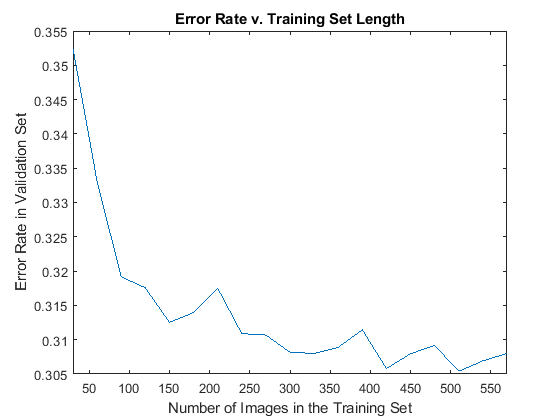

xlim([30,570])                 % adjust the x axis
           
xlabel('Number of Images in the Training Set')      % adding title, xlabel, ylabel 
ylabel('Error Rate in Validation Set')
title('Error Rate v. Training Set Length')